[x,fs] = audioread("s5.wav");
u = 255;
x1 = x(1:8000)

x1 =    -0.0041
   -0.0051
   -0.0031
   -0.0026
   -0.0010
   -0.0010
   -0.0010
   -0.0010
         0
    0.0010


yh = fxquant(mulaw(x1,u),10,'round','sat');
e = mulawinv(yh,u) - x1;
h = histogram(e)

h =   Histogram - 属性:

             Data: [8000×1 double]
           Values: [1×92 double]
          NumBins: 92
         BinEdges: [1×93 double]
         BinWidth: 1.0000e-04
        BinLimits: [-0.0045 0.0047]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


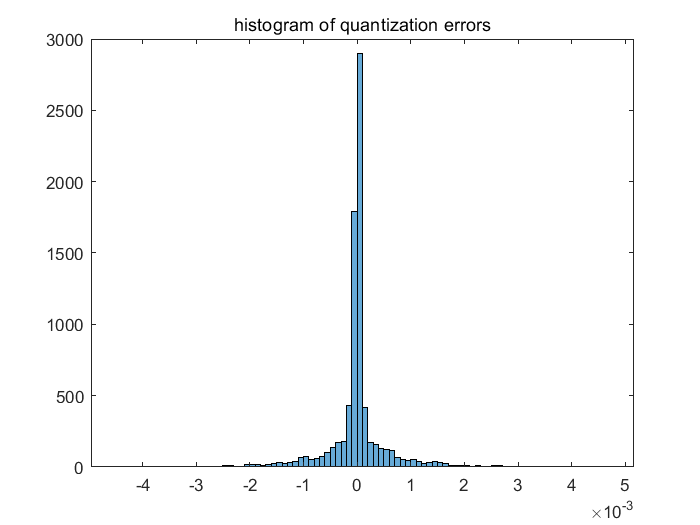

title('histogram of quantization errors')

[pows, freq] = analyse_power_spectrum(e, fs)

pows =     0.0011
    0.0009
    0.0019
    0.0004
    0.0003
    0.0015
    0.0028
    0.0020
    0.0002
    0.0024


freq =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


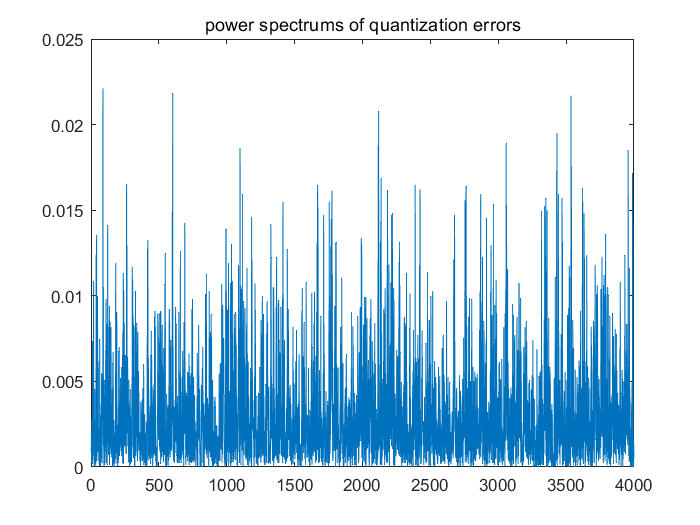

plot(pows)
title('power spectrums of quantization errors')